# Test system using 4 dofs system with proportional damping

*This example demonstrates the use of MPIFD_MIMO on a simulated discrete 4-DOF system. The simulated experiment was written by Baptiste Chomette at LAM (ð'Alembert, Sorbonne Université). *

**INSTRUCTIONS**: run section by section untill the GUI appears. Then follow the steps described to manipulate the GUI, and eventually run the last section.

## 1. Background on the test model

### Modal parameters of the analytical 4 dofs system

`m1=3, m2=1, m3=2, m4=1`

`k1=1, k2=2, k3=1, k4=1`

`c1=c2=c3=c4=0.1`

4 FRF measurements were simulated (one on each dof - use `test_4dofs_proportional.m` to generate the data if not already present) with excitation located on dof 1, and 4 measurements with excitation located on dof 3. The data for accelerance, modility and receptance are located respectively in the files:

- `ACC_tot.mat`

- `MOB_tot.mat`

- `REC_tot.mat`

Each measurement FRF is a `Nf x 1` column vector, and all measurements are concatenated into a `Nf x (No x Ni)` matrix. In the present case, `No=4` and `Ni=2`, hence there are `NoxNi=8` columns in the FRF matrix.

The `Nf x 1` vector of corresponding angular frequencies is stored in the file `omg_tot.mat`

#### Theoretical resonance frequencies

`-- f -- -- xi --`

`0.0494   0.0177`

`0.1203   0.0104`

`0.2037   0.0103`

`0.3059   0.0122`

## 2. Initialization of the required user input

Let's start with receptance measurements, you can later try different types of measurement.

clear all
close all
clc

addpath('MPIFD_MIMO')


%% Initialization
% data type: disp, vel ou acc
frfType = 'disp' ;

% Use complex or Real-valued residues
useRealResidues = false ;

% use residual terms for LF or HF contributions of out-of-band modes?
useLRUR = false ;

% load angular frequency in rad/s and in vector form [Nf x 1] here Nf=3001
load('4dof_example/omg_tot.mat')

% load FRF measurements in matrix form [Nf x (No x Ni)], here [3001 x 8]
load('4dof_example/REC_tot.mat') ;
frf = rec ;

We can now select a particular frequency span to focus on, for instance if measurements have too much noise above a certain frequency.

%% selection of the FRF range using frequency betwen 0.02 and 0.38 Hz
[w1, frf1] = select_frf(w, frf, 0.02,  0.38) ;

% description of the system inupts and outputs
vectAct = [1 3] ; % actuator points: dof 1 and 3 ; has to have length Ni
vectSens = [1 2 3 4] ; % sensors placed on dof 1, 2, 3 and 4 ; length No

% identification using stabilization chart between order 2 and 20
vectOrder = 2:20 ;

% display only the FRFs H11, H31, H13, and H33
listIOVisu = [1 1 ; 3 1 ; 1 3 ; 3 3] ; 

## 3. Starting the GUI

----------------------------------------------------------------------------------------------------
MPIFD-MIMO: Modal Parameters Identification in the Frequency Domain -- Multi-Input - Multi-Output
----------------------------------------------------------------------------------------------------
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Authors :
% Baptiste Chomette, Ecole Centrale de Lyon, LTDS, baptiste.chomette@ec-lyon.fr
% Jean-Loic Le Carrou : Sorbonne Université, d'Alembert, jean-loic.le_carrou@sorbonne-universite.fr
% Sami Karkar : Sorbonne Université, d'Alembert, sami.karkar@free.fr
% François Fabre : Sorbonne Université, d'Alembert, fabrefrancois8@gmail.com
%
% Aknowledgements :
% This work, part of the project Ngombi, was funded by the Agence Nationale de la Recherche
% (French National research agency), Grant No. ANR-19-CE27-0013-01.
%
% License :
% GNU CC BY-NC-SA
%
% Realease : v0 ... 2025
%
% Reference : 
% B

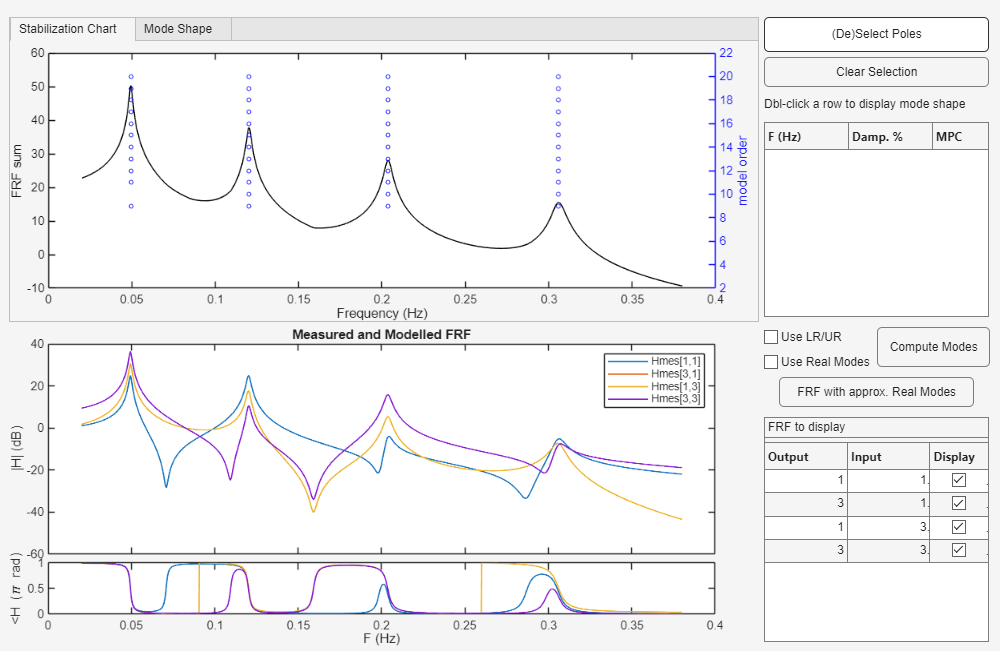

%% start the Identification UI
fig1 = mpifd_mimo(w1, frf1, vectAct, vectSens, vectOrder, useLRUR, ...
    useRealResidues, frfType, listIOVisu) ;

### Using the GUI

The GUI should start and compute the poles of the system for each order in the list provided using the *LSCF algorithm* [1-3]. The stabilization chart is displayed in the top plot, and the measured FRF (magnitude and phase) chosen for display are shown in the lower plot.

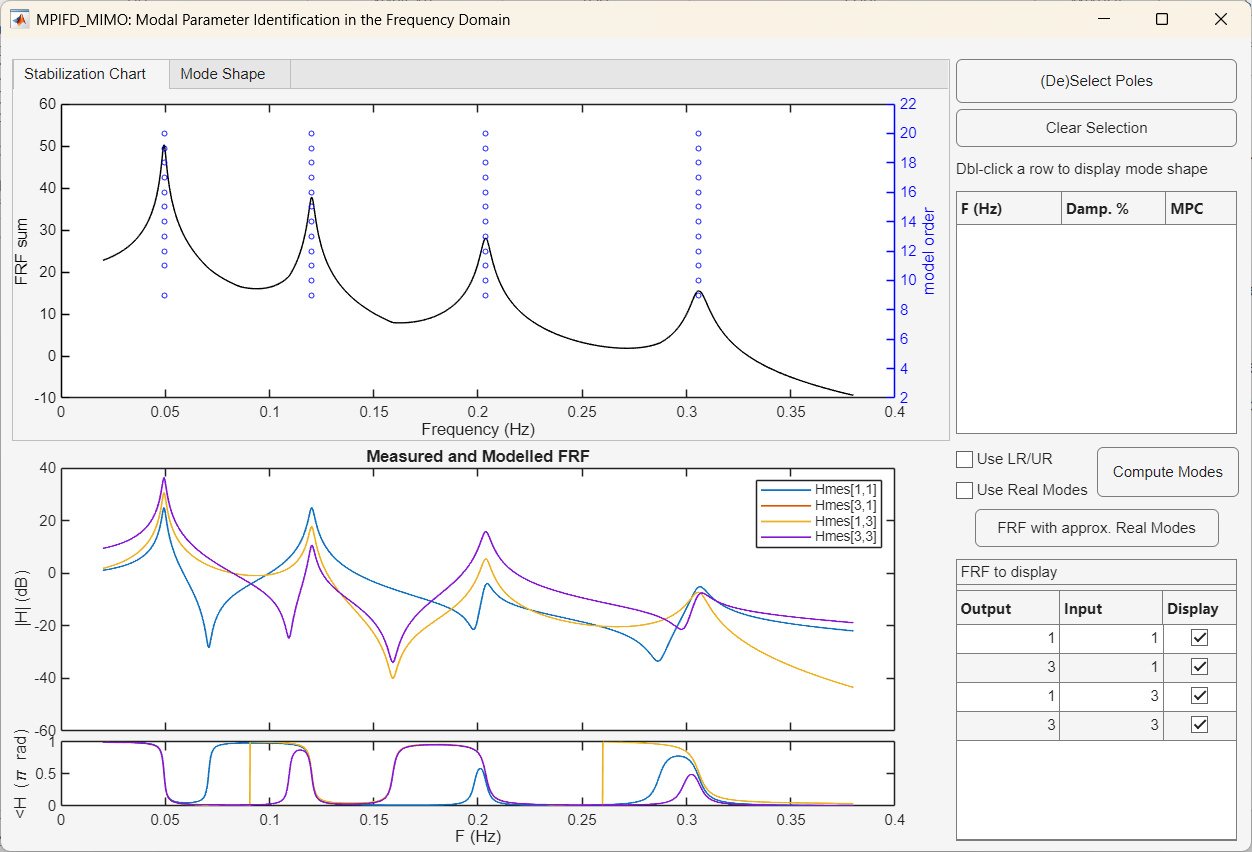

- Click on the "(De)Select Poles" button on the top right corner of the GUI

- The mouse cursor turns into a cross-hair, you can start clicking on the poles (blue circles) that seem stable enough. Here, there are 4 clear resonances. After selecting the desired poles, click on "Validate selection" (same button) and the mouse cursor turns back to normal.

After selecting these 4 poles (see below, highlighted in green) and validating, the list of selected poles appears in the top table on the right (highlighted in green). 

The lower table (highlighted in yellow) allows to hide/show any of the FRFs in the plot thanks to the right-side checkboxes. With a right click you can also permanently delete a row, or add a row. You can also edit manually the table to change which FRFs are displayed.

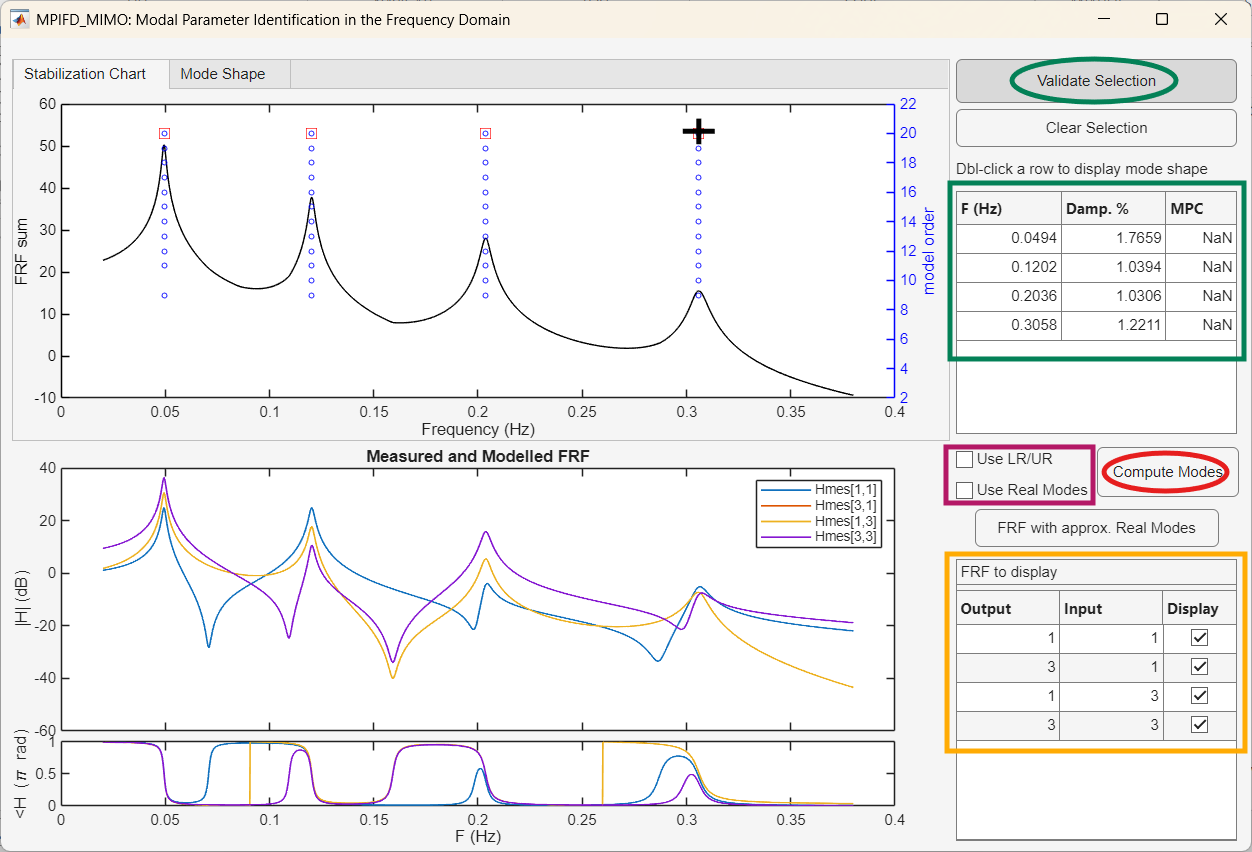

### Computing modes and FRFs

Residues needed to estimate the modal FRFs are computed using the well-known *LSFD algorithm* [4]. There are several options for computing modal FRFs based on the identified poles. Two checkboxes allow for setting these options (highlighted in purple):

- The checkbox "Use LR/UR" allows the user to activate or deactivate the use additional terms **LR** and **UR**, which model the effect of out-of-band modes, and can thus better represent the FRFs in the frequency band of interest.

- The checkbox "Use Real Modes" allows to chose between complex-valued residues (more general case), or real-valued residues (which constrains the problem). Problems with well uncoupled modes will work well with real residues, while if some mode coupling is present or the damping is not proportional, certain modes will be complex-valued.

Once the options chosen (by default, none of the checkboxes are selected), **click on "Compute Modes"** (highlighted in red) to start the computation of residues and modes, based on the selection of poles.

The lower plot now shows additional curves with dashes, corresponding to the modal FRFs computed. If the computation was done using complex modes, the Modal Phase Colinearity parameter (with a value between 0 and 1) [5] is computed and shown in the upper table. Modes with a high MPC are highlighted in green, while modes with very low MPC are highlighted in red. In this example, the modes seem to have perfect MPC, meaning that they are real-valued, despite being computed with complex residues, which reflects a good modal fit, uncoupled modes, and proportional damping.

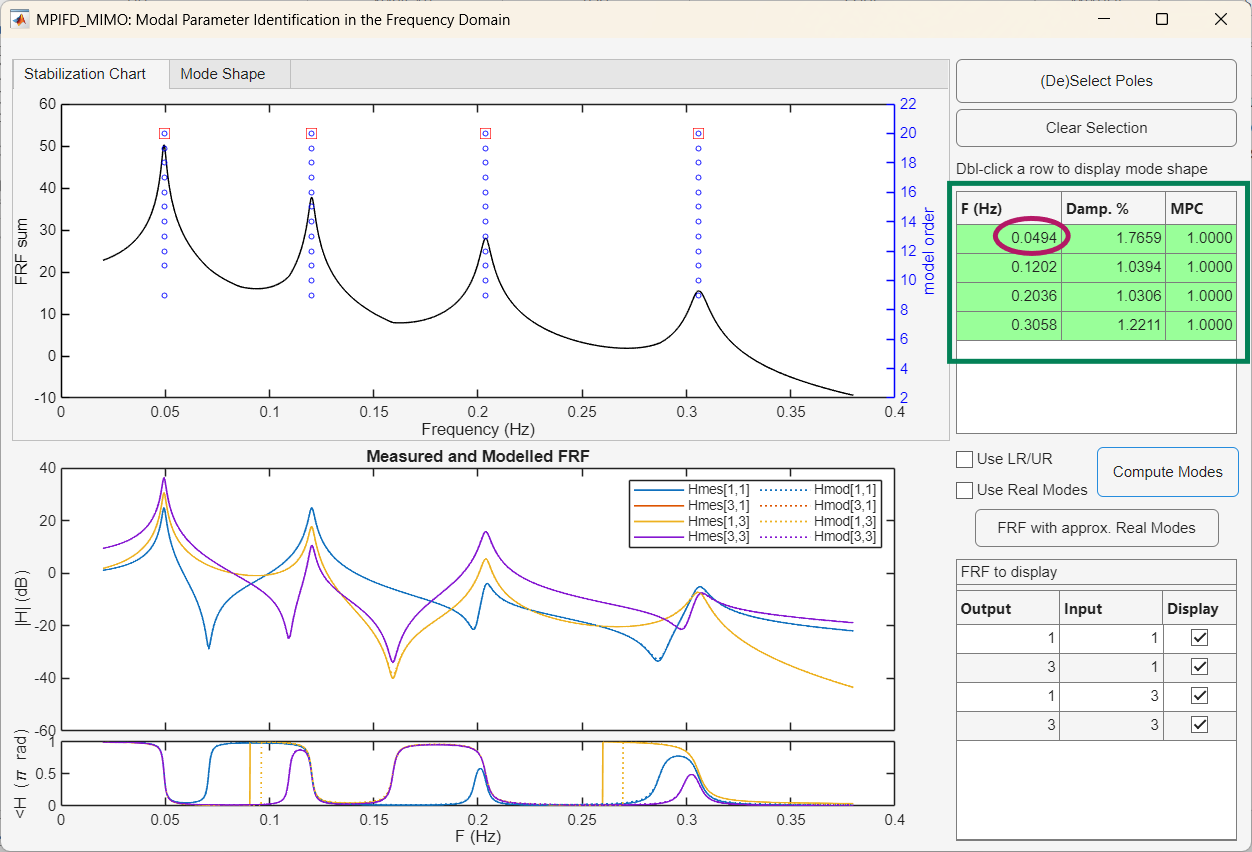

### Displaying mode shapes

By double-clicking on one mode in the upper table, the upper plot switches to the second tab and displays the mode shape. By clicking on the first line, holding the shift key, then double clicking on the last line, the 4 mode shapes are displayed together:

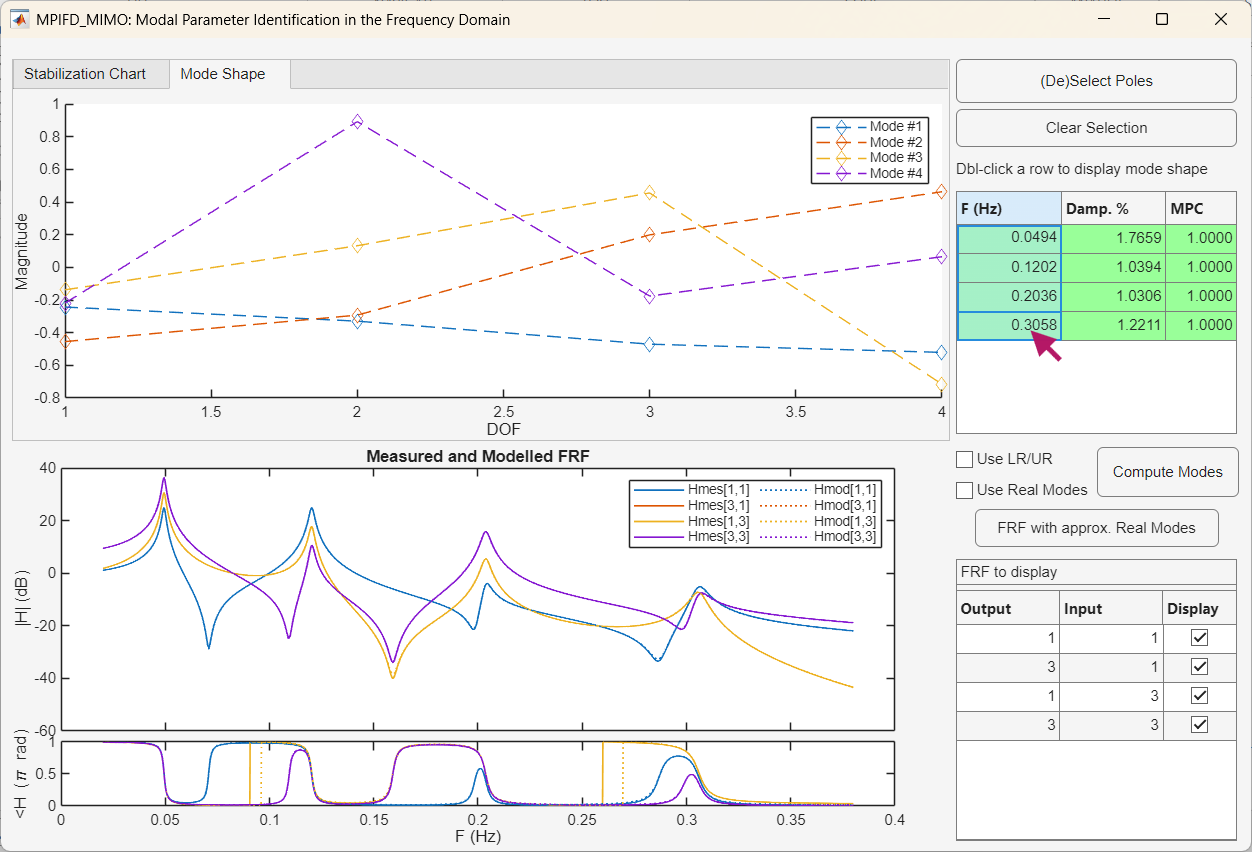

## 4. Manual takeover

We can also interact with the model through the console. For this, we need to extract the data and handles from the GUI.

%% Manual takeover
st = guidata(fig1);

For instance to overlay the analytical mode shapes, use the following commands:

% scaled modes using mass matrix (unitary modal mass)
phi_an = [0.2431 0.4549 -0.1380 -0.2197;
 0.3295 0.2927 0.1321 0.8878 ;
 0.4705 -0.1987 0.4558 -0.1770 ;
 0.5208  -0.4632 -0.7141 0.0657] ;

for iMode=1:4
    if sign(st.id.phir(1,iMode))~=sign(phi_an(1,iMode))
        phi_an(:,iMode) = -phi_an(:,iMode);
    end
end

set(st.axModeShapes,"ColorOrderIndex",1)
set(st.axModeShapes, "NextPlot","add")
plot(st.axModeShapes, phi_an, '-x')
leg=legend(st.axModeShapes);
leg.String(5:8) = {'\phi_1','\phi_2','\phi_3','\phi_4'};

## 5. MAC matrix

Finally, to look at the MAC matrix of the computed modes, you can execute the following code in the command line:

hMACfig = uifigure('Name','MAC Matrix');
haxMAC = uiaxes(hMACfig, 'Position',[10 10 540 400]);
MAC = mac_matrix(st.id.phi, phi_an, haxMAC) ;
xlabel(haxMAC, 'identified modes')
ylabel(haxMAC, 'analytical modes')


## *Credits*

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Authors :
% Baptiste Chomette, Ecole Centrale de Lyon, LTDS, baptiste.chomette@ec-lyon.fr
% Jean-Loic Le Carrou : Sorbonne Université, d'Alembert, jean-loic.le_carrou@sorbonne-universite.fr
% Sami Karkar : Sorbonne Université, d'Alembert, sami.karkar@free.fr
% François Fabre : Sorbonne Université, d'Alembert, fabrefrancois8@gmail.com
%
% Aknowledgements :
% This work, part of the project Ngombi, was funded by the Agence Nationale de la Recherche
% (French National research agency), Grant No. ANR-19-CE27-0013-01.
%
% License :
% GNU CC BY-NC-SA
%
% Realease : v0 ... 2025
%
% Reference : 
% B. Chomette, J-L. Le Carrou, S. Karkar, F. Fabre, ..., JOSS, ...
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## *References*

[1] Van der Auweraer H., P. Guillaume, P. Verboven and S. Vanlanduit, “Application of a Fast-Stabilizing Frequency Domain Parameter Estimation Method,” *ASME Journal of Dynamic Systems, Measurement and Control*, vol. 123, no. 4, pp. 651-658, December 2001.

[2] Polyref

[3] Balmes, MSSP 1997

[4] Sandro Amador, Mahmoud El-Kafafy et al, A New Maximum Likelihood Estimator Formulated in Pole-Residue Modal Model, Applied Sciences 9, 3120, 2019, doi:10.3390/app9153120

[5] Richard S. Pappa, Kenny B. Elliott, and Axel Schenk, "Consistent-mode indicator for the eigensystem realization algorithm. *Journal of Guidance, Control, and Dynamics*, 16(5):852–858, Spetember–October 1993.

## APPENDIX 1

**Analytical mode shapes **`PHI`** using **`norm2`** so that **`norm(phi(:,i)) = 1`

`0.2992    0.6152   -0.1589   -0.2352`

`0.4055    0.3959    0.1521    0.9507`

`0.5791   -0.2688    0.5249   -0.1895`

`0.6409   -0.6265   -0.8223    0.0703`

**Analytical mode shapes **`PHI`** scaled to unit modal mass**

`0.2431    0.4549   -0.1380   -0.2197`

`0.3295    0.2927    0.1321    0.8878 `

`0.4705   -0.1987    0.4558   -0.1770 `

`0.5208   -0.4632   -0.7141    0.0657`